# Flight Data Analysis for Ballooning Flights

## ReadMe

This MATLAB script aims to allow for easy data analysis for stratospheric ballooning flights. Currently it analyzes and plots telemetry data such as altitude, ascent rate, and temperature. At the present it has the capability to analyze data for single balloon flights. Double balloon flight analysis is in the works. It is important that the user imports a CSV file with flight data, and that the column headers of these CSV files follow a very specific format.

## Clear Workspace and Command Line

% Clear the workspace and the command line to avoid variable conflicts
clear all
clc


## File Information

% For starters, it is important the the file you plan on importing has the proper column header
% names. For the proper names, consult the readme or the referenced columns in the "Import Data"
% section. If the data was already been saved to a .mat file, then just load it by running a command
% from the command line.


% To begin you must import the data that you want to analyze. 
%   1. Under the Home tab, click on "Import Data".
%   2. Select and open the correct data file (probably a CSV file).
%   3. Make sure that the Output Type is a table.
%   4. Replace all unimportable cells with NaNs (this should be set by default).
%   5. Click on "Import Selection".

% Manually insert the name of the table that you just imported
data_table = GL150SICKOMODE;

Undefined function or variable 'GL150_SICKOMODE'.

flight = 'GL150';

save_file = flight + "_import_data";


## Import Data

% Import relevant columns of data in column vectors

minutes = table2array(data_table(:,"Minutes"));
satellites = table2array(data_table(:,"Satellites"));
avg_ascent_rate = table2array(data_table(:,"AverageAscentRate"));
instant_ascent_rate = table2array(data_table(:,"AscentRate"));
latitude = table2array(data_table(:,"Lat"));
longitude = table2array(data_table(:,"Long"));
external_temp = table2array(data_table(:,"ExtTempC"));
internal_temp = table2array(data_table(:,"IntTempC"));
battery_temp = table2array(data_table(:,"BatTempC"));
bat_heat_status = table2array(data_table(:,"BatteryHeaterStatus"));
sensor_seat_status = table2array(data_table(:,"SensorHeaterStatus"));
system_state = table2array(data_table(:,"SystemState"));
GPS_altitude = table2array(data_table(:,"Altitudeft"));
control_altitude = table2array(data_table(:,"ControlAltitude"));
pressurePSI = table2array(data_table(:,"PressurePSI"));
pressureATM = table2array(data_table(:,"PressureATM"));

save(save_file)


## Analyze Data Bounds

% Find the index for the start of the flight
prompt = 'Do you want to manually enter an index for the start of the flight? (y/n)\n';
answer = input(prompt,'s')

answer = 'n'


if (answer == 'y')
    prompt = 'Enter the index: ';
    start_index = input(prompt);
else
    hold_array = find(control_altitude > 0);
    first_alt = control_altitude(hold_array(1));
    hold_array = find(control_altitude > first_alt + 300);
    start_index = hold_array(1);
end


% Find the index for the maximum altitude
prompt = 'Do you want to manually enter an index for the maximum altitude? (y/n)\n';
answer = input(prompt,'s')

answer = 'n'


if (answer == 'y')
    prompt = 'Enter the index: ';
    max_alt_index = input(prompt);
elseif (max(control_altitude) == max(GPS_altitude))
    max_alt_index = find(control_altitude == max(control_altitude));
else
    max_alt_index = find(GPS_altitude == max(GPS_altitude));
end


% Find the index for the end of the flight
prompt = 'Do you want to manually enter an index for the end of the flight? (y/n)\n';
answer = input(prompt,'s')

answer = 'n'


if (answer == 'y')
    prompt = 'Enter the index: ';
    end_index = input(prompt);
else
    hold_array = GPS_altitude((max_alt_index + 1):end);
    hold_array = hold_array(hold_array > 0);
    index_array = find(hold_array < min(hold_array) + 100);
    end_index = find(GPS_altitude == hold_array(index_array(1)),1);
end


% Create an array of ticks to be used for altitude axes
top_alt_tick = round(max(GPS_altitude),-4);
if (top_alt_tick < max(GPS_altitude))
    top_alt_tick = top_alt_tick + 10^4;
end

alt_ticks = 10^4:10^4:top_alt_tick;


% Create an array of ticks to be used for temperature ticks
min_temp = min([min(battery_temp(battery_temp > -100)),min(internal_temp(internal_temp > -100)),...
    min(external_temp(external_temp > -100))]);
min_temp_tick = round(min_temp,-1);
if (min_temp_tick > min_temp)
    min_temp_tick = min_temp_tick - 10;
end

max_temp = max([max(battery_temp(battery_temp < 70)),max(internal_temp(internal_temp < 70)),...
    max(external_temp(external_temp < 70))])

max_temp = 26.8750

max_temp_tick = round(max_temp,-1);
if (max_temp_tick < max_temp)
    max_temp_tick = max_temp_tick + 10;
end

temp_ticks = min_temp_tick:10:max_temp_tick;


## **Plot Data**

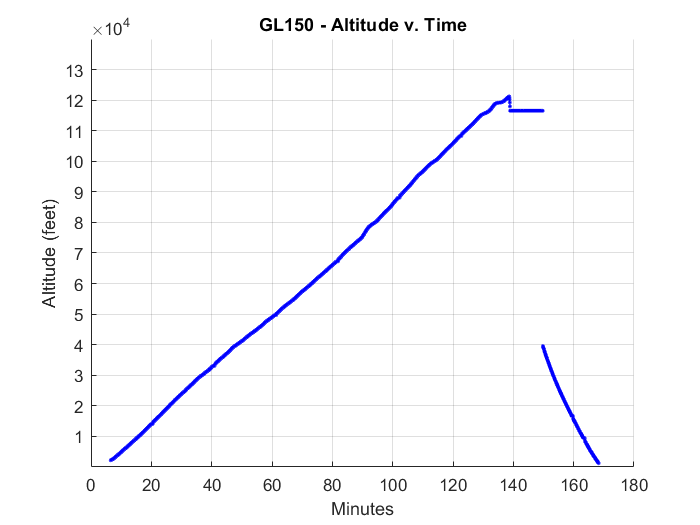

% Plot altitude v. time
figure(1), clf
% Select one of two options below, and comment out the other
scatter(minutes(start_index:end_index),GPS_altitude(start_index:end_index),'b.');
%scatter(minutes(start_index:end_index),control_altitude(start_index:end_index),'b.');
grid on, hold on
title(sprintf('%s - Altitude v. Time',flight));
ylabel('Altitude (feet)');
yticks(alt_ticks)
xlabel('Minutes');

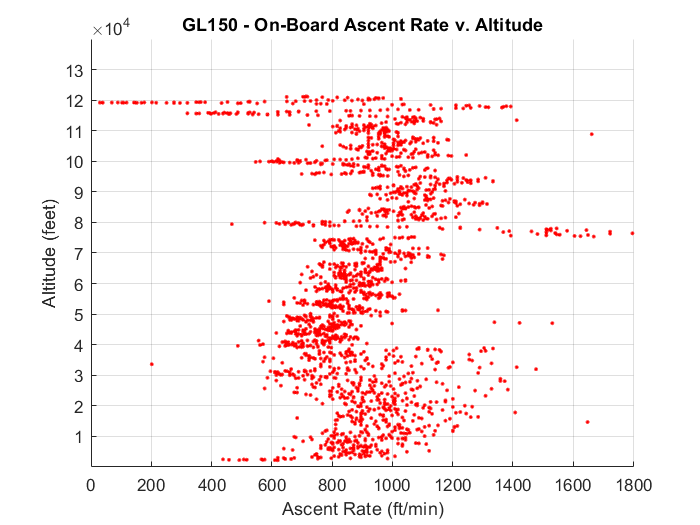



% Plot instant ascent rate v. altitude
figure(2), clf
instant_ascent_rate = instant_ascent_rate.*60;
scatter(instant_ascent_rate(start_index:max_alt_index),control_altitude(start_index:max_alt_index),'r.');
grid on, hold on;
title(sprintf('%s - On-Board Ascent Rate v. Altitude',flight));
ylabel('Altitude (feet)')
yticks(alt_ticks)
xlabel('Ascent Rate (ft/min)')
xlim([0 2*mean(instant_ascent_rate(start_index:max_alt_index))]);

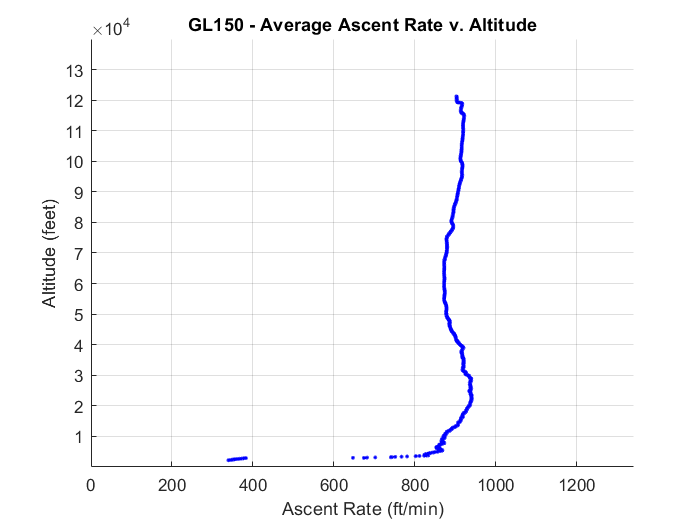



% Plot average ascent rate v. altitude
figure(3), clf
avg_ascent_rate = avg_ascent_rate.*60;
scatter(avg_ascent_rate(start_index:max_alt_index),control_altitude(start_index:max_alt_index),'b.');
grid on, hold on;
title(sprintf('%s - Average Ascent Rate v. Altitude',flight));
ylabel('Altitude (feet)')
yticks(alt_ticks)
xlabel('Ascent Rate (ft/min)')
xlim([0 1.5*mean(avg_ascent_rate(start_index:max_alt_index))]);

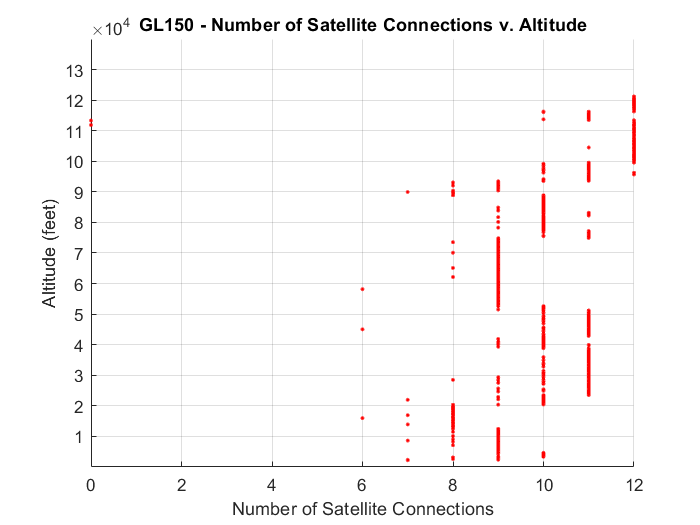



% Plot number of satellites v. altitude
figure(4), clf
scatter(satellites(start_index:max_alt_index),control_altitude(start_index:max_alt_index),'r.');
grid on, hold on;
title(sprintf('%s - Number of Satellite Connections v. Altitude',flight));
ylabel('Altitude (feet)')
yticks(alt_ticks)
xlabel('Number of Satellite Connections')

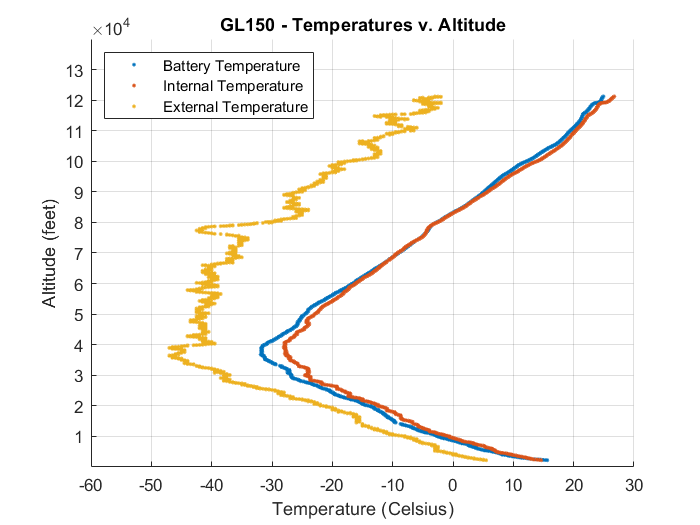



% Plot tempeeratures v. altitude up to max altitude
figure(5), clf
hold on, grid on, zoom on
scatter(battery_temp(start_index:max_alt_index),control_altitude(start_index:max_alt_index),'.');
scatter(internal_temp(start_index:max_alt_index),control_altitude(start_index:max_alt_index),'.');
scatter(external_temp(start_index:max_alt_index),control_altitude(start_index:max_alt_index),'.');
title(sprintf('%s - Temperatures v. Altitude',flight));
ylabel('Altitude (feet)')
yticks(alt_ticks)
xlabel('Temperature (Celsius)')
xlim([min(temp_ticks) max(temp_ticks)])
xticks(temp_ticks)
legend('Battery Temperature','Internal Temperature','External Temperature','location','northwest')